% change directory in order for relative references to work
cd(fileparts(matlab.desktop.editor.getActiveFilename))

# ANN

You have learned the principles of a neural network - in particular, a feed forward network - during the lectures. We will not focus on implementing the backpropagation ourselves, as it is far from trivial to do this in a generic way.

#### Training a model

To actually train a model we need four things:

- An objective function, that evaluates how well a model is doing given some input data. This is the loss function we have encountered in previous sessions.

- The trainable parameters of the model. The parameters depend on the design of the model (one or multiple layers, the type of layers etc.)

- A collection of data points that will be provided to the objective function, our training data that is provided in a way that is useable (i.e. any preprocessing should already be done. Also keep in mind that a neural network is unable to deal with missing values.

- An optimiser that will update the model parameters appropriately. There are a lot of other optimizers that exist, [adam](https://arxiv.org/abs/1412.6980) is one that is used frequently.

#### Stopping the training

As before we will need to impose some conditions on when to stop. We can use the following approaches:

- include an upper limit on the number of epochs (total number of passes over the data)

- stop updates after reaching a predefined performance measure (e.g. accuracy >= 0.9999)

- modify the learning rate if there are no further improvement after m epochs since the last one. This comes down do refining the search for an optimum.

## Application 1 - Univariate regression with a neural network

clear; close all force; clc

In previous courses (algebra & statistics), you have already encountered linear regression. An algebraic approach was used to find the best possible parameter(s). We will start by have a look at training a regression model iteratively. In order for this to work, we need:

- data

- a model (e.g. $$y= w_0 + w_1$x$)

- a loss function or even a complexity function (e.g. the $$L_2$ $norm)

- a method for training, i.e. updating the weights (e.g. gradient descent)

You can generate you're own shallow neural network by hand using the "network" command. Below we generate a network that can be used for linear regression, i.e. one weight value and one bias (or offset). Refer to the documentation for detailed info.

A linear network is similar to the perceptron, but its transfer function is linear rather than hard-limiting. This allows their outputs to take on any value, whereas the perceptron output is limited to either 0 or 1. Linear networks, like the perceptron, can only solve linearly separable problems.

For the loss function, we can use the mean square error that we will try to minimize.

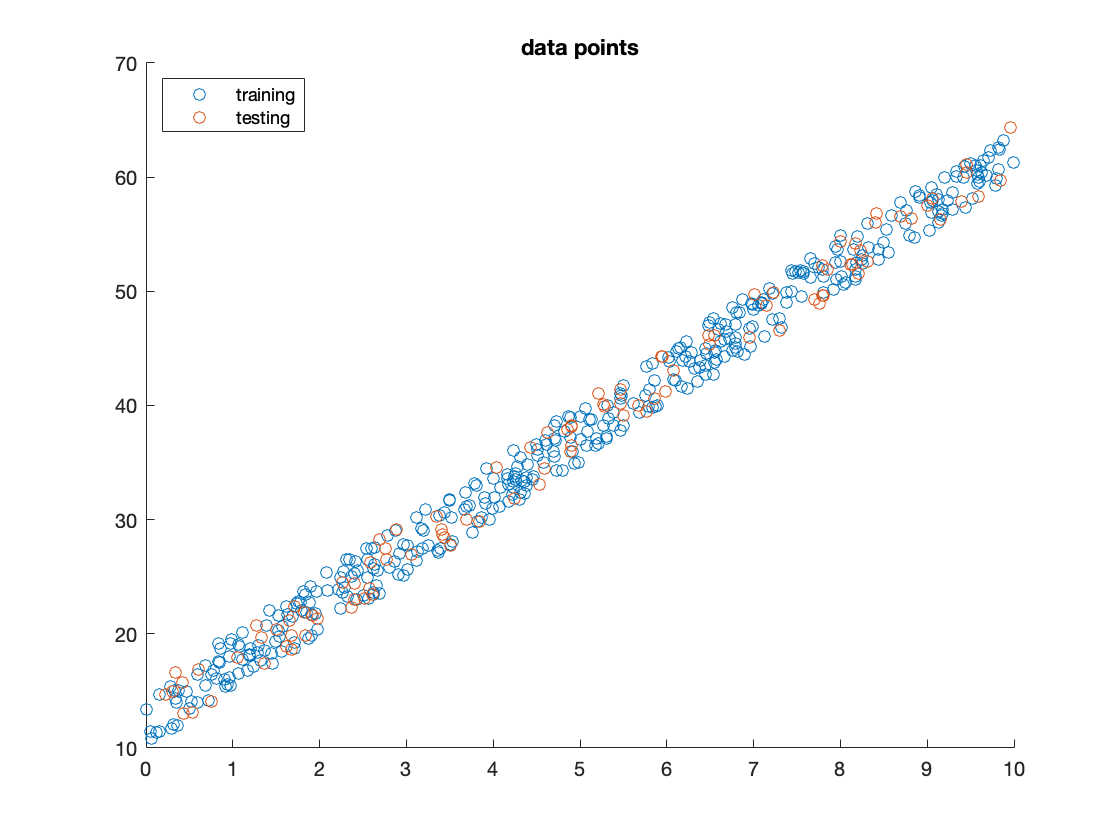

% generate the data:
x = rand(500,1)*10; % uniform data
y = 5*x + 10 + rand(size(x))*5; % value with noise
% split in training and validation data
idx = randperm(500);
x_train = x(idx(1:400)); y_train = y(idx(1:400));
x_val = x(idx(401:end)); y_val = y(idx(401:end));
% plot data
figure()
scatter(x_train,y_train,"DisplayName","training");
hold on
scatter(x_val, y_val,"DisplayName","testing");

legend("location","northwest")
title("data points")

% single layer neural net with input of size 1 with a bias on the first (and only layer)
layers = [featureInputLayer(1,'Name','inputlayer') ... % input layer 
          fullyConnectedLayer(1,'Name','connected') ... % single layer with one weight (and its bias)
          regressionLayer('Name','regressionlayer')... % indicates the output should be RMSE

layers =   1×3 Layer array with layers:

     1   'inputlayer'        Feature Input       1 features
     2   'connected'         Fully Connected     1 fully connected layer
     3   'regressionlayer'   Regression Output   mean-squared-error

    ]
% coherence check network layout
analyzeNetwork(layers)

% set training options
options = trainingOptions('adam', ...
    'Plots','training-progress', ... % Plot training progress
    'MaxEpochs',4000,...
    'Verbose',false,...              % no output of progress in command window
    "ValidationData",{x_val y_val}, ...% give validation data to analyse model performance
    "ValidationFrequency",500, ...% validate every 500 iterations
    "Shuffle","every-epoch"); % shuffle every epoch
% train the network
[net, info] = trainNetwork(x_train,y_train,layers,options);

% properties of the net
net.Layers(2).Weights

ans = single
5.6235

net.Layers(2).Bias

ans = single
8.2707

% properties had we done a simple regression
reg = polyfit(x_train,y_train,1)

reg =     4.9808   12.4270


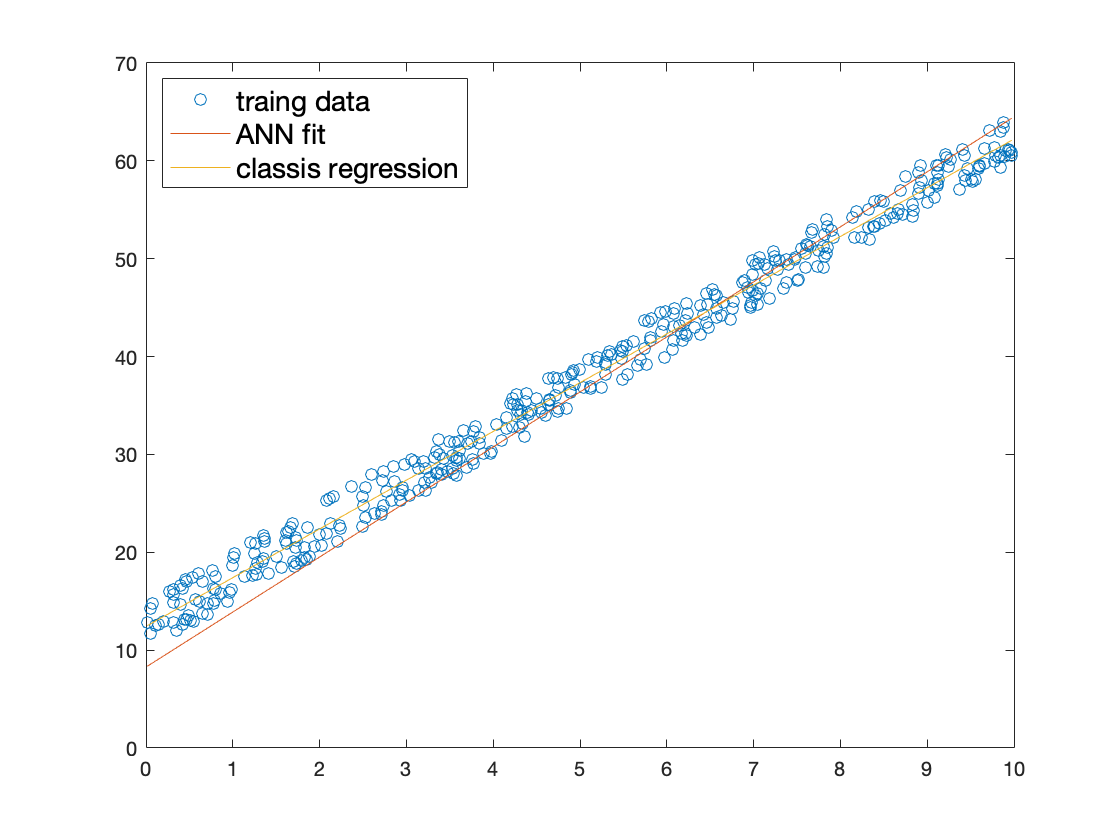

% illustration
figure()
plot(x_train, y_train,'o','DisplayName','traing data');
hold on
plot(x_train, net.Layers(2).Weights * x_train + net.Layers(2).Bias, '-','DisplayName','ANN fit');
plot(x_train, polyval(reg, x_train), '-','DisplayName','classis regression');
legend("fontsize",14,"location","northwest");

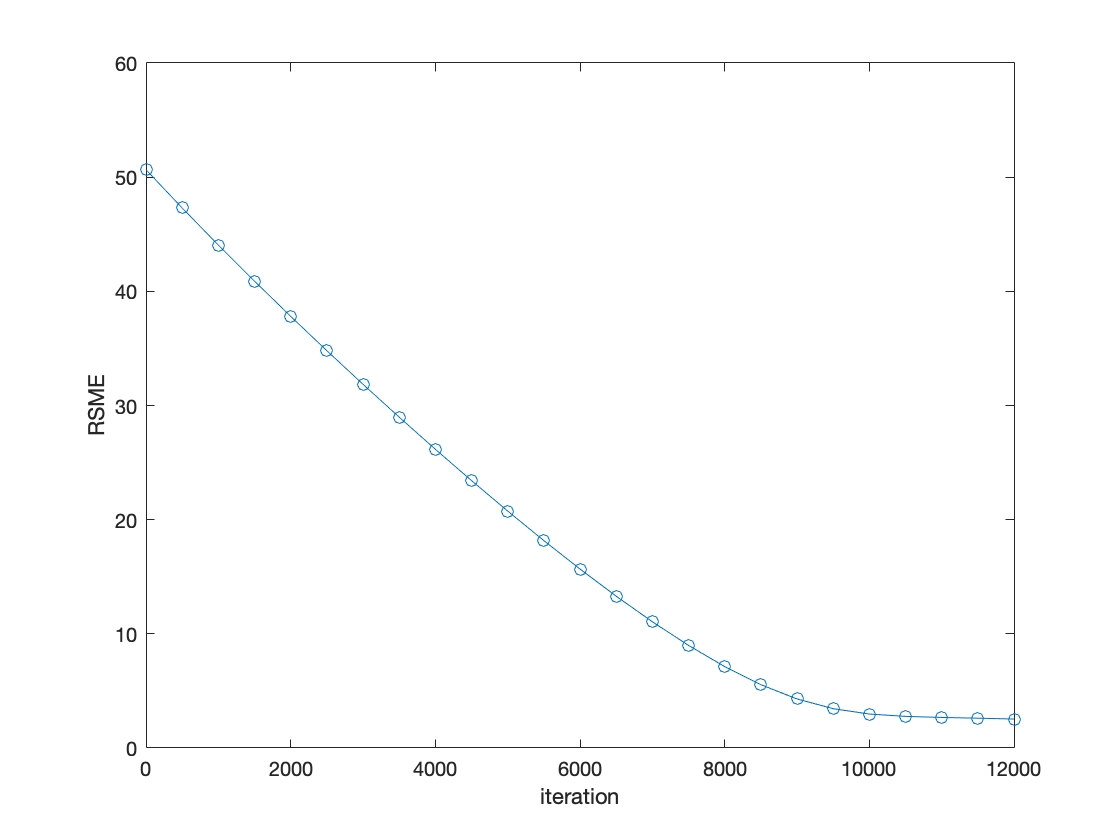

% evolution of the loss function
idx = ~isnan(info.ValidationRMSE); % non-NaN values
its = 1:length(idx); its = its(idx); % iterations
figure()
plot(its, info.ValidationRMSE(idx),'-o','DisplayName','loss');
xlabel('iteration'); ylabel('RSME')

## OLD MATLAB (<=2020b):

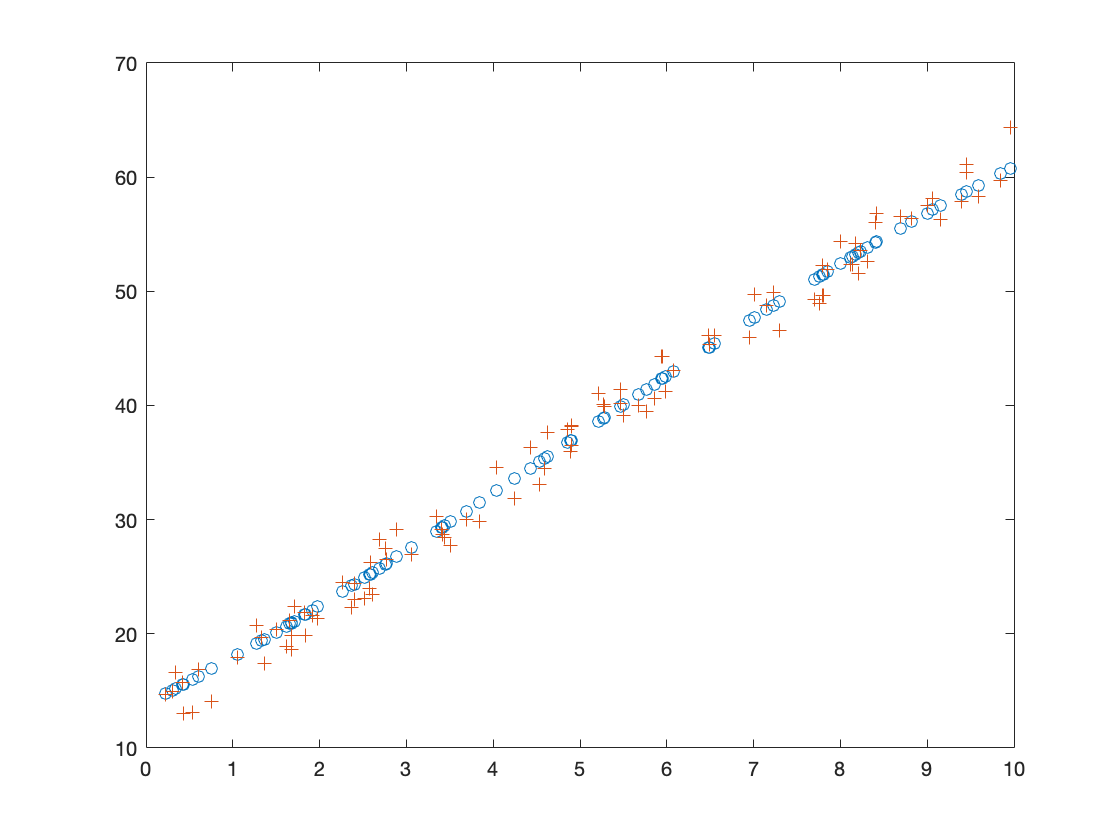

mynet = feedforwardnet(1);
mynet = train(mynet,x_train',y_train');
y_pred = mynet(x_val');
figure
plot(x_val, y_pred', "o");
hold on
plot(x_val, y_val,'+')

## Application 2 - Classification with a neural network (non-separable data)

clear; close all

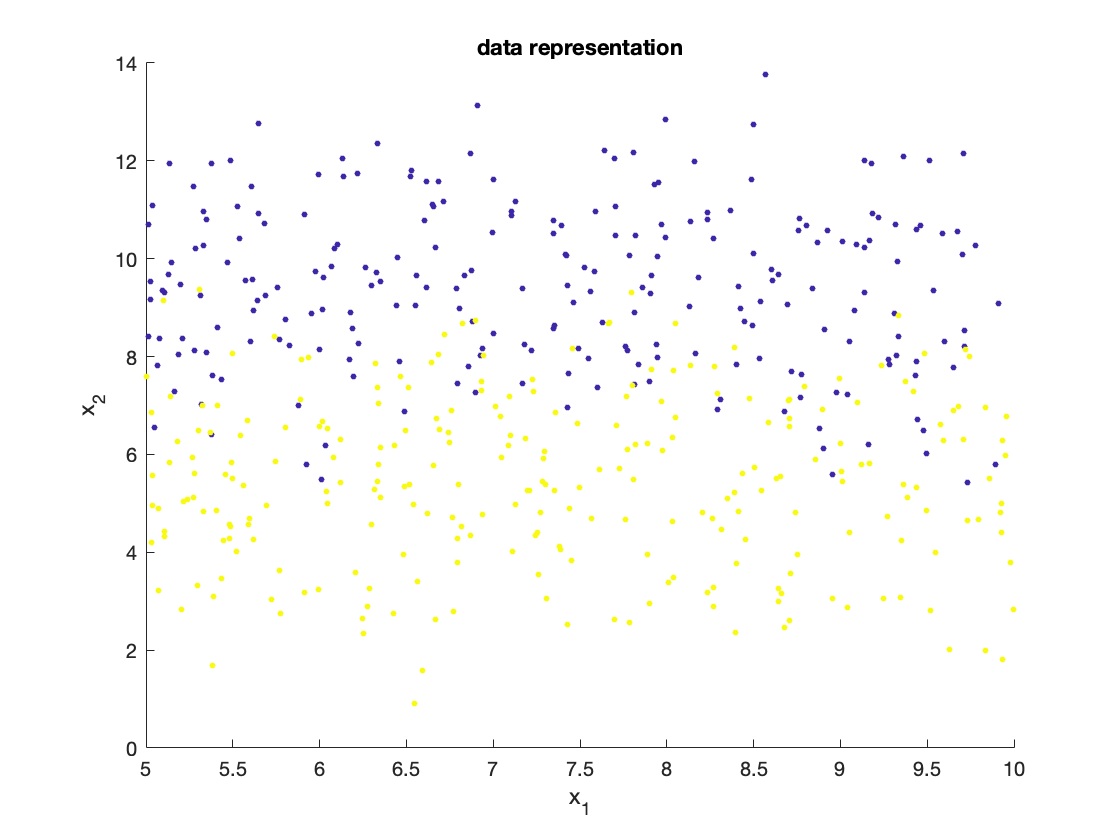

% data lay-out
n = 500; n1 = 240; n2 = n- n1;
X = rand(n,2)*5+5;
X(1:n1,2) = X(1:n1,2) + 2 + randn(n1,1);
X(n1+1:end,2) = X(n1+1:end,2) - 2 + randn(n-n1,1);
Y = categorical([ones(n1,1); zeros(n2,1)], [1 0], {'blue','yellow'});
colormap copper;
figure()
scatter(X(:,1), X(:,2), 10,Y,'filled');
xlabel('x_1'); ylabel('x_2');
title('data representation')

As we are dealing with a classification task, you can no longer use the numerical value as a result. We will build a network that deals with the classification task. 

First of all, we need to do some preparations before we can train the network

% split data in train and test set
numObservationsTrain = floor(0.85*n);
numObservationsTest = n - numObservationsTrain;
% array of random indices corresponding to the observations 
% and partition it using the partition sizes
% (required as data is sorted)
idx = randperm(n);
idxTrain = idx(1:numObservationsTrain);
idxTest = idx(numObservationsTrain+1:end);
% actual data partitioning
XTrain = X(idxTrain,:); XTest = X(idxTest,:);
YTrain = Y(idxTrain); YTest = Y(idxTest,:);

The data is prepared, now we can focus on the actual layout of the network. You can find an overview of all types of available layer by looking at "List of Deep Learning Layers"

layers = [
    % input layer with the correct amount of features and normalisation
    featureInputLayer(size(X,2),'Normalization', 'zscore','Name','feature input')
    % fully connected layer 
    fullyConnectedLayer(10,'Name', 'dense layer')
    % activation layer using hyperbolic tangent (tanh) on the layer inputs
    tanhLayer('Name','activation layer')
    % fully connected layer matching the number of classes
    fullyConnectedLayer(2,'Name', 'class as numbers')
    % softmax: normalize the output of a network to a probability distribution)
    softmaxLayer("Name","softmax")
    % classication layer: use highest probability to assign a class
    classificationLayer("Name","classification")
    ]

layers =   6×1 Layer array with layers:

     1   'feature input'      Feature Input           2 features with 'zscore' normalization
     2   'dense layer'        Fully Connected         10 fully connected layer
     3   'activation layer'   Tanh                    Hyperbolic tangent
     4   'class as numbers'   Fully Connected         2 fully connected layer
     5   'softmax'            Softmax                 softmax
     6   'classification'     Classification Output   crossentropyex

analyzeNetwork(layers)

A number of options can be set for the training of the network (the example below uses the Adam optimizer)

options = trainingOptions('adam', ...
    'MiniBatchSize',256, ... % size of each batch. Why limit this? 
    'Shuffle','every-epoch', ... % motivation?
    'Plots','training-progress', ... % Plot training progress
    'Verbose',false, ... % no output of progress in command window
    'MaxEpochs',1000,... 
    "ValidationData",{XTest, YTest},...
    "ValidationPatience",5);

We now have:

- the data

- a neural network architecture

- a set of options for the solver

and are able to train our model:

[net, info] = trainNetwork(XTrain,YTrain,layers,options);

The info item contains a trace that we can plot.

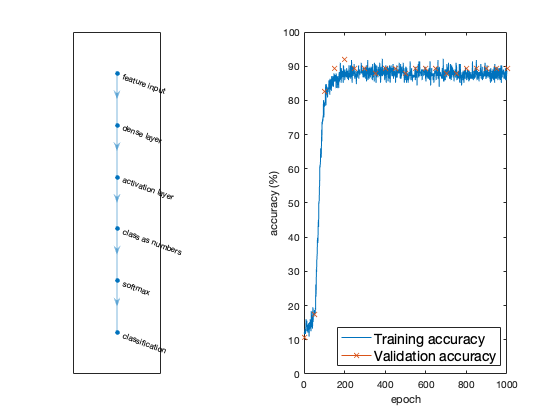

figure()
subplot(1,4,1)
plot(net)
subplot(1,4,3:4)
plot(info.TrainingAccuracy,'DisplayName','Training accuracy');
hold on
plot(info.ValidationAccuracy,'-x','DisplayName','Validation accuracy');
ylim([0,100]);
xlabel('epoch'); ylabel('accuracy (%)');
legend('Location',"southeast",'FontSize',14);

## Application 3 - Classification with a neural network (categorical data)

Up to now our data has been numerical, however you can use a neural network for categorical input as well. But this requires some data transformations.

- If the categorical data is ordinal (e.g. 'small', 'medium', 'large'), you can simply convert these into numbers (e.g. 1, 2, 3).

- If there is not quantitative relationship between the unique values of the categorical variable, one-hot-encoding can be used. 

This is just the tip of the iceberg. A recent overview of this topic is given in [this publication](https://journalofbigdata.springeropen.com/track/pdf/10.1186/s40537-020-00305-w.pdf). 

We will be using one-hot-encoding in the example below. For each unique value of the categorical variable, a new dummy variable is created. The dummy variable is either one or zero.

The dataset that we will be using (and a larger one) can be found [here](https://archive.ics.uci.edu/ml/datasets/Bank+Marketing).

### Load the data

clear; close all force; clc
D = readtable('./Data/bank-additional.csv');

head(D)

ans = 8×21 table
    age          job             marital            education            default        housing         loan           contact        month     day_of_week    duration    campaign    pdays    previous       poutcome        emp_var_rate    cons_price_idx    cons_conf_idx    euribor3m    nr_employed      y   
    ___    ________________    ___________    _____________________    ___________    ___________    ___________    _____________    _______    ___________<

There are multiple categorical variables in this dataset such as 'job', 'marital', 'education' etc. We will use one-hot encoding and some prepocessing to build the model.

### Preprocessing

% variable to be predicted
y = table(categorical(D.y));
% apply data preprocessing
job = D.job;
job = preprocessor(job);
job = onehotencode(job);
marital  = D.marital;
marital = preprocessor(marital);
marital = onehotencode(marital);
default = D.default;
default = preprocessor(default);
default = onehotencode(default);
housing = D.housing;
housing = preprocessor(housing);
housing = onehotencode(housing);

% data we will be using for the model
d = [job marital default housing y];
head(d)

ans = 8×23 table
    job_admin.    job_blue-collar    job_entrepreneur    job_housemaid    job_management    job_retired    job_self-employed    job_services    job_student    job_technician    job_unemployed    job_unknown    marital_divorced    marital_married    marital_single    marital_unknown    default_no    default_unknown    default_yes    housing_no    housing_unknown    housing_yes    Var1
    __________    _______________    ________________    _____________    ______________    ___________

### Building and training the network

% network layout
layers = [
    % input layer with the correct amount of features and normalisation
    featureInputLayer(width(d)-1,'Name','input layer')
    % fully connected layer
    fullyConnectedLayer(20,'Name', 'dense layer')
    % activation layer using hyperbolic tangent (tanh) on the layer inputs
    sigmoidLayer('Name', 'sigmoid activation')
    % fully connected layer matching the number of classes
    fullyConnectedLayer(2,'Name', 'binary output')
    % softmax: normalize the output of a network to a probability distribution)
    softmaxLayer("Name","softmax")
    % classication layer: use highest probability to assign a class
    classificationLayer("Name","classification")
    ];
% training options
options = trainingOptions('adam', ...
    'MiniBatchSize',256, ... 
    'Shuffle','every-epoch', ... % motivation?
    'Plots','training-progress', ... % Plot training progress
    'Verbose',false, ... % no output of progress in command window
    'MaxEpochs',50);

analyzeNetwork(layers)

% actual training
[net, info] = trainNetwork(d{:,1:end-1},d{:,end},layers,options);

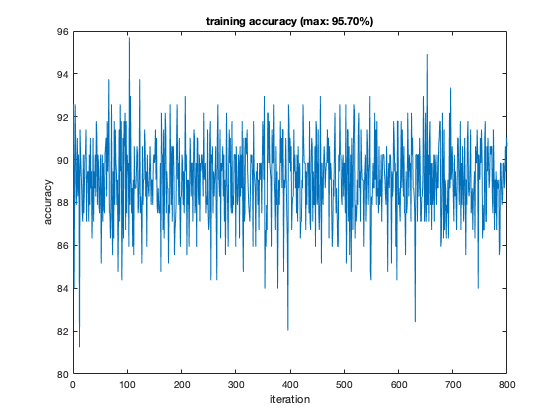

figure();
plot(info.TrainingAccuracy)
xlabel('iteration'); ylabel('accuracy');
title(sprintf('training accuracy (max: %1.2f%%)', max(info.TrainingAccuracy)))

## Application 4 - Revisiting the handwritten number recognition

clear; close all force; clc

### Fixed network

We will try to do handwritten number recognition again, this time using a neural network.

D = readtable('./Data/MNIST-train.csv');
% modify datatype
D.label = categorical(D.label);
% use only 10% of data for training
part = cvpartition(D.label,"HoldOut", 0.9, "Stratify", true);
% limit data for training
d = D(part.training,:);
% data for testing (limit to 1k entries)
t = D(part.test,:);
t = t(1:1000,:);
% quick look into data
head(d)

ans = 8×785 table
    label    pixel0    pixel1    pixel2    pixel3    pixel4    pixel5    pixel6    pixel7    pixel8    pixel9    pixel10    pixel11    pixel12    pixel13    pixel14    pixel15    pixel16    pixel17    pixel18    pixel19    pixel20    pixel21    pixel22    pixel23    pixel24    pixel25    pixel26    pixel27    pixel28    pixel29    pixel30    pixel31    pixel32    pixel33    pi

% network layout
layers = [
    % input layer with the correct amount of features and normalisation
    featureInputLayer(28^2,'Normalization', 'zscore','Name','input layer')
    % fully connected layer
    fullyConnectedLayer(50,'Name', 'dense layer')
    % activation layer using hyperbolic tangent (tanh) on the layer inputs
    sigmoidLayer('Name', 'sigmoid activation')
    %   tanhLayer('Name','activation layer')
    % fully connected layer matching the number of classes
    fullyConnectedLayer(10,'Name', 'class as numbers')
    % softmax: normalize the output of a network to a probability distribution)
    softmaxLayer("Name","softmax")
    % classication layer: use highest probability to assign a class
    classificationLayer("Name","classification")
    ]

layers =   6×1 Layer array with layers:

     1   'input layer'          Feature Input           784 features with 'zscore' normalization
     2   'dense layer'          Fully Connected         50 fully connected layer
     3   'sigmoid activation'   Sigmoid                 sigmoid
     4   'class as numbers'     Fully Connected         10 fully connected layer
     5   'softmax'              Softmax                 softmax
     6   'classification'       Classification Output   crossentropyex

% training options
options = trainingOptions('adam', ...
    'MiniBatchSize',128, ... 
    'Shuffle','every-epoch', ... % motivation?
    'Plots','none', ... % Plot training progress
    'Verbose',true, ... % no output of progress in command window
    'MaxEpochs',1000,... 
    "ValidationData",{t{:,2:end}, t{:,1}},...
    "ValidationPatience",5);
% actual training
[net, info] = trainNetwork(d{:,2:end},d{:,1},layers,options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       10.16% |        9.30% |       2.4914 |       2.4093 |          0.0010 |
|       2 |          50 |       00:00:00 |       82.03% |       82.10% |       0.9532 |       0.9383 |          0.0010 |
|       4 |         100 |       00:00:00 |       89.84% |       85.60% |       0.6126 |       0.6837 |          0.0010 |
|       5 |         150 |       00:00:01 |       89.84% |       87.20% |       0.4802 |   

info.FinalValidationAccuracy

ans = 89.7000

### Optimize layout and training settings

In the previous section, we simply tried a network layout that, however it is possible to optimize the network layout as well. The application below illustrates this using Baysian optimisation.

% Define our parameters
optimVars = [
    optimizableVariable('Hiddenlayercounts',[1 3],'Type','integer')
    optimizableVariable('InitialLearnRate',[1e-2 1],'Transform','log')
    optimizableVariable('Hiddenlayersize',[10 200],'Type','integer')
    ]

optimVars =   3×1 optimizableVariable array with properties:

    Name
    Range
    Type
    Transform
    Optimize


|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Hiddenlayerc-| InitialLearn-| Hiddenlayers-|
|      | result |             | runtime     | (observed)  | (estim.)    | ounts        | Rate         | ize          |
|====================================================================================================================|
|    1 | Best   |       0.094 |      4.5799 |       0.094 |       0.094 |            1 |      0.04338 |          137 |


|    2 | Best   |       0.093 |      3.2719 |       0.093 |     0.09346 |            3 |       0.2217 |           78 |


|    3 | Accept |       0.104 |       1.451 |       0.093 |    0.093409 |            1 |      0.43565 |           28 |


|    4 | Accept |       0.112 |      7.5807 |       0.093 |    0.093768 |            2 |     0.013089 |           57 |


|    5 | Accept |       0.109 |       4.917 |       0.093 |      0.1024 |            3 |      0.20279 |           87 |


|    6 | Accept |        0.12 |      2.8566 |       0.093 |     0.10533 |            3 |      0.44126 |           28 |


|    7 | Best   |       0.077 |      2.1091 |       0.077 |    0.092053 |            1 |      0.70742 |          137 |


|    8 | Accept |       0.094 |      1.6837 |       0.077 |    0.091954 |            1 |      0.45603 |          137 |


|    9 | Accept |       0.095 |      1.7155 |       0.077 |    0.092091 |            1 |      0.41491 |           33 |


|   10 | Accept |        0.09 |      1.6664 |       0.077 |    0.090373 |            1 |      0.41097 |          138 |


|   11 | Accept |       0.095 |       1.863 |       0.077 |    0.090821 |            1 |       0.4253 |          135 |


|   12 | Accept |        0.09 |      1.7943 |       0.077 |    0.090267 |            1 |      0.50149 |          138 |


|   13 | Accept |        0.09 |      2.0857 |       0.077 |    0.089842 |            1 |      0.34916 |          139 |


|   14 | Accept |       0.088 |      1.6877 |       0.077 |    0.089504 |            1 |       0.4483 |          141 |


|   15 | Accept |       0.083 |      1.5409 |       0.077 |    0.088721 |            1 |      0.49017 |          143 |


|   16 | Accept |       0.086 |      1.9267 |       0.077 |    0.087306 |            1 |      0.49908 |          146 |


|   17 | Accept |       0.087 |      1.5043 |       0.077 |    0.086543 |            1 |      0.51107 |          148 |


|   18 | Accept |       0.087 |      1.8802 |       0.077 |    0.086567 |            1 |      0.60138 |          145 |


|   19 | Accept |       0.087 |       1.729 |       0.077 |    0.086262 |            1 |      0.48247 |          154 |


|   20 | Accept |       0.089 |      1.5298 |       0.077 |    0.086292 |            1 |      0.46244 |           70 |


|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Hiddenlayerc-| InitialLearn-| Hiddenlayers-|
|      | result |             | runtime     | (observed)  | (estim.)    | ounts        | Rate         | ize          |
|====================================================================================================================|
|   21 | Accept |        0.09 |      1.4445 |       0.077 |    0.077564 |            1 |      0.47668 |           56 |


|   22 | Accept |       0.083 |      2.2911 |       0.077 |    0.077524 |            1 |      0.83591 |          137 |


|   23 | Accept |       0.084 |      3.6553 |       0.077 |    0.077561 |            2 |      0.70765 |          138 |


|   24 | Accept |       0.084 |      2.0047 |       0.077 |    0.077807 |            1 |      0.70885 |          133 |


|   25 | Accept |       0.092 |      1.6782 |       0.077 |    0.077827 |            1 |      0.34352 |          153 |


|   26 | Accept |       0.087 |      1.8723 |       0.077 |    0.083177 |            1 |      0.65624 |          137 |


|   27 | Accept |       0.088 |      5.5285 |       0.077 |    0.082815 |            1 |      0.95571 |          141 |


|   28 | Accept |       0.096 |      2.0049 |       0.077 |    0.082745 |            2 |       0.2945 |           65 |


|   29 | Accept |       0.082 |      1.8497 |       0.077 |    0.082576 |            1 |      0.79784 |          135 |


|   30 | Accept |       0.086 |       1.766 |       0.077 |    0.082453 |            1 |      0.85938 |          135 |


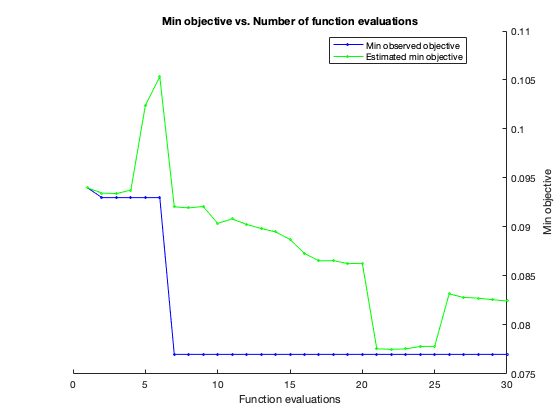


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 94.1933 seconds
Total objective function evaluation time: 73.4688

Best observed feasible point:
    Hiddenlayercounts    InitialLearnRate    Hiddenlayersize
    _________________    ________________    _______________

            1                0.70742               137      

Observed objective function value = 0.077
Estimated objective function value = 0.082453
Function evaluation time = 2.1091

Best estimated feasible point (according to models):
    Hiddenlayercounts    InitialLearnRate    Hiddenlayersize
    _________________    ________________    _______________

            1                0.70742     

% Create the objective function for the Bayesian optimizer (defined at the end)
ObjFcn = makeObjFcn(d{:,2:end},d{:,1},t{:,2:end}, t{:,1});
% Run the optimisation
BayesObject = bayesopt(ObjFcn,optimVars, ...
    'MaxTime',14*60*60, ...
    'IsObjectiveDeterministic',false, ...
    'UseParallel',false);

BayesObject.XAtMinObjective

ans = 1×3 table
    Hiddenlayercounts    InitialLearnRate    Hiddenlayersize
    _________________    ________________    _______________

            1                0.70742               137      


## Application 5 - DIY

Use one of the "Sample Data Sets for Shallow Neural Networks" and try some neural networks for yourself!

=> help nndatasets

clear; close all force; clc

## Supporting functions

function ObjFcn = makeObjFcn(XTrain,YTrain,XValidation,YValidation)
% MAKEOBJFCN Objective Function for neural network optimization
% 
% This function returns a function that is used for training and evaluating the network given
% a set of optimisation options (optVars)
%
% The variables XTrain,YTrain,XValidation,YValidation are known in the
% scope of makeObjFcn. These are used to build another function that
% determines and returns the validation error.
% returned object is a function handle
    ObjFcn = @valErrorFun;
    % function within the function that uses XTrain,YTrain,XValidation,YValidation
    function [valError] = valErrorFun(optVars)
        % identify number of classes
        numClasses = numel(unique(YTrain));
        % build the neural network
        layers = [
            % input layer with the correct amount of features and normalisation
            featureInputLayer(28^2,'Normalization', 'zscore','Name','input layer')
            % followed by the hidden block (1-3 layers of varying size)
            hiddenblock(optVars.Hiddenlayercounts, optVars.Hiddenlayersize)
            % fully connected layer matching the number of classes
            fullyConnectedLayer(numClasses,'Name', 'class as numbers')
            % softmax: normalize the output of a network to a probability distribution)
            softmaxLayer("Name","softmax")
            % classication layer: use highest probability to assign a class
            classificationLayer("Name","classification")
            ];
        
        % Set the training options
        miniBatchSize = 256;
        % validate after each minibatch
        validationFrequency = floor(numel(YTrain)/miniBatchSize);
        options = trainingOptions('sgdm', ... 
            'InitialLearnRate',optVars.InitialLearnRate, ... % set initial learning rate
            'MaxEpochs',60, ...                              % don't do more than 60 epochs
            'LearnRateSchedule','piecewise', ...             % updates the learning rate 
            'LearnRateDropPeriod',40, ...                    % every 40 epochs 
            'LearnRateDropFactor',0.1, ...                   % by multiplying with a factor 0.1
            'MiniBatchSize',miniBatchSize, ... 
            'Shuffle','every-epoch', ...
            'Verbose', false, ...                             % don't print progress of training a specific model
            'Plots','none', ...                              % don't plot progress of training a specific model
            'ValidationData',{XValidation,YValidation}, ...  % set validation data
            'ValidationFrequency',validationFrequency, ...   % set when to validate the data
            "ValidationPatience",5);      
        
        % train the network with the current settings
        trainedNet = trainNetwork(XTrain,YTrain,layers,options);
        % close training figure
        close(findall(groot,'Tag','NNET_CNN_TRAININGPLOT_UIFIGURE'))
        
        YPredicted = classify(trainedNet,XValidation);
        valError = 1 - mean(YPredicted == YValidation);
    
            
    end
end

function layers = hiddenblock(Hiddenlayercounts,Hiddenlayersize)
    layers = [
        % fully connected layer
        fullyConnectedLayer(Hiddenlayersize)
        % activation layer using hyperbolic tangent (tanh) on the layer inputs
        sigmoidLayer
    ];
    % repeat this block as much as needed
    layers = repmat(layers,Hiddenlayercounts,1);
end

function un = preprocessor(var)
% PREPROCESSOR helper function for onehot encoding
    % get variable name 
    name = inputname(1);
    %fprintf('name: %s', name);
    % transform into categorical
    un = categorical(var);
    % get unique names
    names = unique(un);
    % make new names
    namecell = {};
    newnames = {};
    for i = 1:length(names)
        namecell(end+1) = cellstr(sprintf("%s", names(i)));
        newnames(end+1) = cellstr(sprintf("%s_%s", name, names(i)));
    end
    % replace names
    un = table(renamecats(un, namecell, newnames));
end